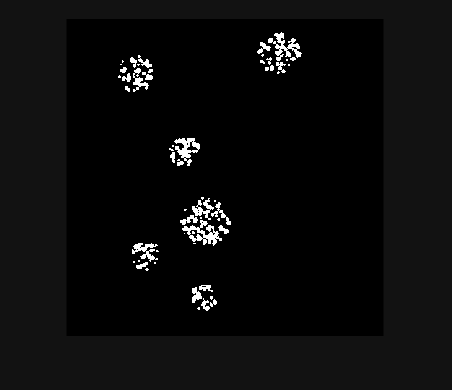

rng(1)                          % remove or change for different results each run

imgSize     = [512 512];        % [rows cols]
numClusters = 6;
minR        = 20;               % smallest cluster radius (pixels)
maxR        = 60;               % largest cluster radius
margin      = 20;               % minimum gap between clusters (and the border)
dotDensity  = 0.02;             % dots per pixel of cluster area

img = false(imgSize);
[X, Y] = meshgrid(1:imgSize(2), 1:imgSize(1));

%% 1. Place cluster zones that don't touch each other
centers = zeros(0,2);
radii   = zeros(0,1);
tries   = 0;

while size(centers,1) < numClusters && tries < 10000
    tries = tries + 1;
    r = minR + (maxR - minR) * rand;                 % random cluster size
    c = [ (r+margin) + (imgSize(2) - 2*(r+margin)) * rand, ...   % x
          (r+margin) + (imgSize(1) - 2*(r+margin)) * rand ];     % y

    if isempty(radii) || all(hypot(centers(:,1)-c(1), centers(:,2)-c(2)) > radii + r + margin)
        centers(end+1,:) = c;
        radii(end+1,1)   = r;
    end
end

if size(centers,1) < numClusters
    warning('Only placed %d of %d clusters. Reduce sizes/margin or enlarge the image.', ...
            size(centers,1), numClusters);
end

%% 2. Fill each zone with white dots of varying size
for k = 1:size(centers,1)
    nDots = max(3, round(dotDensity * pi * radii(k)^2));

    for d = 1:nDots
        dotR  = 1.5 + 2.5 * rand;                    % dot radius, 1.5 to 4 px
        ang   = 2*pi*rand;
        dist  = sqrt(rand) * (radii(k) - dotR);      % uniform spread, dot stays inside zone
        cx    = centers(k,1) + dist*cos(ang);
        cy    = centers(k,2) + dist*sin(ang);

        img = img | ((X - cx).^2 + (Y - cy).^2 <= dotR^2);
    end
end

%% 3. Save and display
imwrite(img, 'clusters.png');
imshow(img)

%clusters = imread("clusters.png");
%clustersCC = bwconncomp(clusters,4)
%clusterLabel = labelmatrix(clustersCC);
%clusterRGB = label2rgb(clusterLabel,"jet","k","shuffle");
%imshow(clusterRGB)
%stats = regionprops("table",clusterLabel,"Area", "Centroid")


%k = clustersCC.NumObjects
%pixelSize = 3
%pixelArea = pixelSize^2
%Areas = stats.Area;
%Areas_um = stats.Area * pixelArea;
%plot(Areas_um)



rng(2)                                   % change or remove for a different image each run

%% Parameters
imgSize   = [3200 3200];                   % [rows cols]
numBlobs  = 150;                         % target number of particles
minSide   = 2;                           % smallest blob: 2x2 pixels
maxSide   = 5;                           % largest blob:  5x5 pixels
minGap    = 3;                           % minimum empty pixels between blobs

%% 1. Clean binary image with non-touching blobs
clean    = false(imgSize);
occupied = false(imgSize);
truth    = zeros(0,3);                   % [centerX centerY side] for validation
count = 0;
tries = 0;

while count < numBlobs && tries < 20000
    tries = tries + 1;
    s = randi([minSide maxSide]);                        % blob side length
    r = randi([minGap+1, imgSize(1) - s - minGap + 1]);  % top row
    c = randi([minGap+1, imgSize(2) - s - minGap + 1]);  % left column

    % Region including the required gap around the blob
    gapRows = r-minGap : r+s-1+minGap;
    gapCols = c-minGap : c+s-1+minGap;

    if ~any(occupied(gapRows, gapCols), 'all')
        clean(r:r+s-1, c:c+s-1)    = true;
        occupied(r:r+s-1, c:c+s-1) = true;
        count = count + 1;
        truth(end+1,:) = [c + (s-1)/2, r + (s-1)/2, s];
    end
end
fprintf("Placed %d blobs\n", count);

Placed 150 blobs



%% 2. Turn it into a realistic grayscale image
I = 0.15 + 0.60*double(clean);           % dark gray background, bright particles
I = imgaussfilt(I, 0.8);                 % optical blur

[X, Y] = meshgrid(1:imgSize(2), 1:imgSize(1));
illum = 0.12*(X/imgSize(2)) + 0.08*(Y/imgSize(1));   % uneven illumination gradient
I = min(max(I + illum, 0), 1);           % keep values in [0,1]

%% 3. Add noise
noisy = imnoise(I, 'gaussian', 0, 0.003);            % sensor noise
noisy = imnoise(noisy, 'salt & pepper', 0.01);       % random hot/dead pixels

%% 4. Save and display
imwrite(noisy, 'noisyParticles.png');
imwrite(clean, 'cleanParticles.png');    % ground truth for checking your results

figure
%subplot(1,2,1), imshow(clean), title("Clean (ground truth)")
%subplot(1,2,2), imshow(noisy), title("Noisy")

**Image Pre-Processing: **

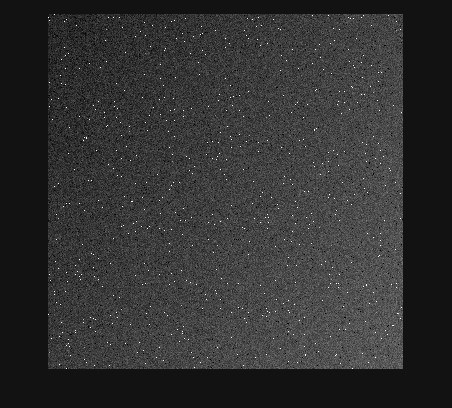

profile on
model = imread("noisyParticles.png");
clean_model = imread("cleanParticles.png");
imshow(model)

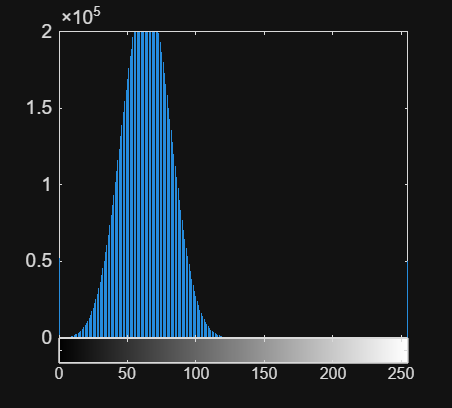

imageGray = im2gray(model); %Grayscale Conversion
imhist(imageGray)

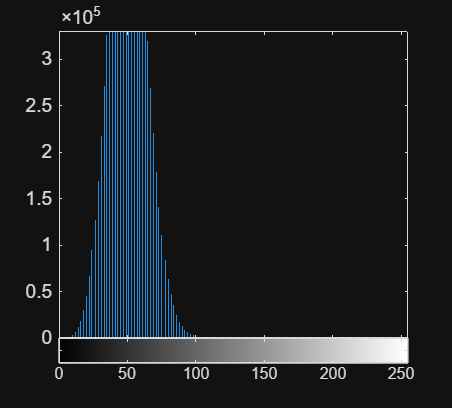

SE = strel("diamond",5); %Structuring Element Radius 
imTH = imtophat(imageGray,SE); %Background Subtraction -> Contrast Gained
imageAdj = imadjust(imTH,[0 125/255]); %Linear Contrast Stretch
imageMed = medfilt2(imageAdj,[3 3],"symmetric"); %Median Filter 
imhist(imageMed)

BW = imbinarize(imageMed);
score = niqe(imageMed)

score = 6.4609

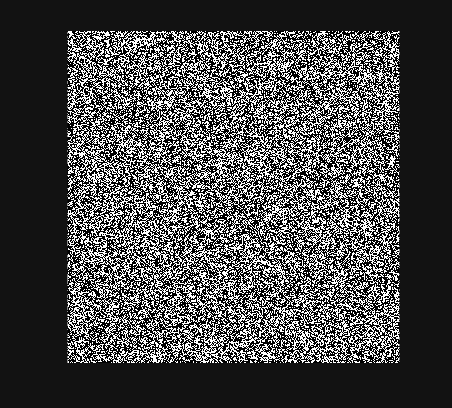

imshow(BW)

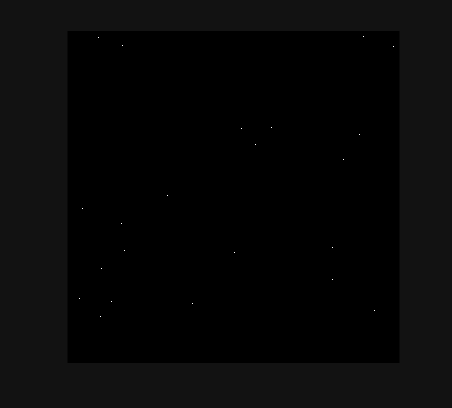

imshow(clean_model)

**Particle Identification and Property Measurement**

particleCC = bwconncomp(BW,4)

particleCC = struct with fields:
    Connectivity: 4
       ImageSize: [3200 3200]
      NumObjects: 126085
    PixelIdxList: {1×126085 cell}


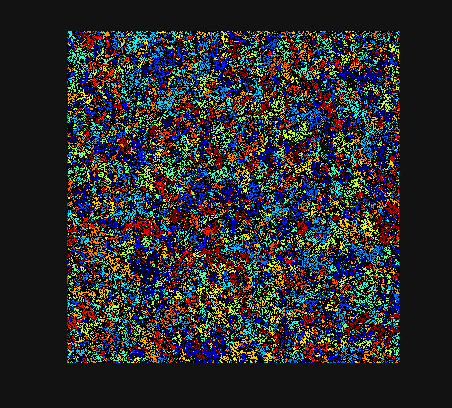

particleLabel = labelmatrix(particleCC);
particleRGB = label2rgb(particleLabel,"jet","k","shuffle");
imshow(particleRGB)

stats = regionprops("table",particleLabel,"Area", "Centroid")

stats = 126085×2 table
    Area        Centroid    
    ____    ________________

       1         1        11
      12    1.8333    14.833
       1         1        25
    2309    44.518    60.962
       1         1        47
      36    4.4167    50.361
       1         1        57
      30       3.8    59.967
      14    3.4286    68.143
      55    6.2182    80.745
       6    2.1667    79.667
     589    28.908    109.65
       1         1       109
      98    8.3571    117.97
       4       1.5     132.5
       2       1.5       139





k = particleCC.NumObjects

k = 126085

pixelSize = 3

pixelSize = 3

pixelArea = pixelSize^2

pixelArea = 9

Areas = stats.Area;
Areas_um = stats.Area * pixelArea;
FPR = 100 * (150 - particleCC.NumObjects) / (150 + particleCC.NumObjects)

FPR = -99.7623



profile viewer



particleCC_clean = bwconncomp(clean_model,4)

particleCC_clean = struct with fields:
    Connectivity: 4
       ImageSize: [3200 3200]
      NumObjects: 150
    PixelIdxList: {1×150 cell}


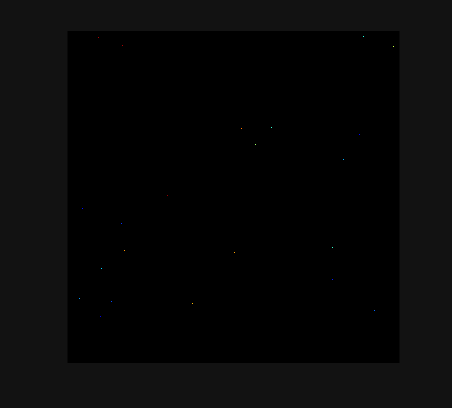

particleLabel_clean = labelmatrix(particleCC_clean);
particleRGB_clean = label2rgb(particleLabel_clean,"jet","k","shuffle");
imshow(particleRGB_clean)

stats_clean = regionprops("table",particleLabel_clean,"Area", "Centroid")

stats_clean = 150×2 table
    Area       Centroid    
    ____    _______________

     25        13      3050
     16      19.5     703.5
      9        31      2289
     16      46.5    1215.5
     25        94      1845
     16     114.5    2578.5
     16     142.5    2568.5
     16     143.5    1709.5
     16     214.5     171.5
      9       257       565
     25       298        65
      4     310.5    1194.5
      4     312.5    1370.5
      4     316.5     204.5
     16     319.5    2256.5
     16     319.5    2753.5



k_clean = particleCC_clean.NumObjects

k_clean = 150

Areas_clean = stats_clean.Area;
Areas_um_clean = stats_clean.Area * pixelArea;
FPR = 100 * (150 - particleCC_clean.NumObjects) / (150 + particleCC.NumObjects)

FPR = 0

% Initialize image pre-processing:
%conartist = imread("conartist.jpg"); % Read original image
%imshow(conartist) % Show original image
%conartistgray = im2gray(conartist); % Convert image to grayscale
%conartistAdapt = adapthisteq(conartistgray); % Adaptive histogram equalization
%conartistAdj = imhistmatch(conartistAdapt,conartistgray); % Adjusts conartistAdapt to match the intensity dist. of conartistgray
%imshowpair(conartistAdapt,conartistAdj,"montage")

%conartistMask = imbinarize(conartistAdj);
%imshow(conartistMask)
%CC = bwconncomp(conartistMask)
%conartistMask = imfill(~conartistMask,"holes");
%imshowpair(conartist, ~conartistMask, "montage");